Proyecto

data = readtable('data/base/count_per_month.csv')

data = 79×2 table
    releaseDate    cant
    ___________    ____

    {'2010-02'}     1  
    {'2010-09'}     1  
    {'2010-10'}     1  
    {'2010-12'}     2  
    {'2011-02'}     1  
    {'2011-08'}     1  
    {'2011-10'}     1  
    {'2011-11'}     1  
    {'2011-12'}     1  
    {'2012-08'}     4  
    {'2012-09'}     1  
    {'2012-10'}     2  
    {'2012-11'}     5  
    {'2012-12'}     1  
    {'2013-02'}     1  
    {'2013-03'}     2  


% Probando con las fechas
%datetime(,'InputFormat','yyyy/MM/dd HH:mm:ss.S')
date = data{1,"releaseDate"}

date = 1×1 cell array
    {'2010-02'}


class(date)

ans = 'cell'

datetime(datatable{:,'releaseDate'},'InputFormat','yyyy-MM')

ans = 79×1 datetime array
   01-Feb-2010
   01-Sep-2010
   01-Oct-2010
   01-Dec-2010
   01-Feb-2011
   01-Aug-2011
   01-Oct-2011
   01-Nov-2011
   01-Dec-2011
   01-Aug-2012
   01-Sep-2012
   01-Oct-2012
   01-Nov-2012
   01-Dec-2012
   01-Feb-2013
   01-Mar-2013
   01-Apr-2013
   01-May-2013
   01-Nov-2013
   01-Dec-2013
   01-Jan-2014
   01-Apr-2014
   01-May-2014
   01-Jul-2014
   01-Oct-2014
   01-Feb-2015
   01-Apr-2015
   01-May-2015
   01-Jun-2015
   01-Jul-2015


% Probando la clase MobileAppDataset
objDataset = MobileAppDataset()

objDataset =   MobileAppDataset with no properties.


objDataset.getCountPerMonthTable()

ans = 79×2 table
    releaseDate    cant
    ___________    ____

    {'2010-02'}     1  
    {'2010-09'}     1  
    {'2010-10'}     1  
    {'2010-12'}     2  
    {'2011-02'}     1  
    {'2011-08'}     1  
    {'2011-10'}     1  
    {'2011-11'}     1  
    {'2011-12'}     1  
    {'2012-08'}     4  
    {'2012-09'}     1  
    {'2012-10'}     2  
    {'2012-11'}     5  
    {'2012-12'}     1  
    {'2013-02'}     1  
    {'2013-03'}     2  


% Accediendo a datos con expresiones
datatable = objDataset.getCountPerMonthTable();
datatable{1,'releaseDate'}{:}

ans = '2010-02'

% Método getCountPerMonth() de la clase MobileAppDataset
[fechas, cantidades] = objDataset.getCountPerMonth()

fechas = 79×1 datetime array
   01-Feb-2010
   01-Sep-2010
   01-Oct-2010
   01-Dec-2010
   01-Feb-2011
   01-Aug-2011
   01-Oct-2011
   01-Nov-2011
   01-Dec-2011
   01-Aug-2012
   01-Sep-2012
   01-Oct-2012
   01-Nov-2012
   01-Dec-2012
   01-Feb-2013
   01-Mar-2013
   01-Apr-2013
   01-May-2013
   01-Nov-2013
   01-Dec-2013
   01-Jan-2014
   01-Apr-2014
   01-May-2014
   01-Jul-2014
   01-Oct-2014
   01-Feb-2015
   01-Apr-2015
   01-May-2015
   01-Jun-2015
   01-Jul-2015


cantidades =      1
     1
     1
     2
     1
     1
     1
     1
     1
     4


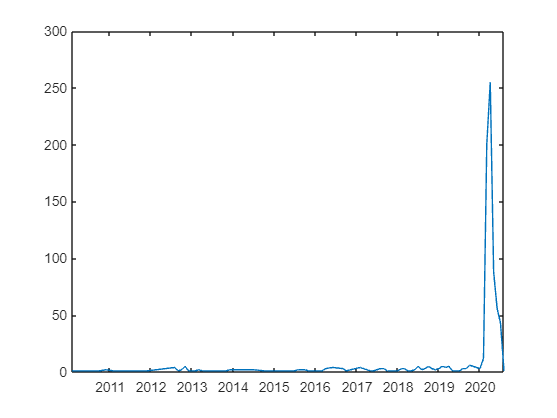

plot(fechas, cantidades)

% Configuración de Matlab con Python
pyenv()

ans =   PythonEnvironment with properties:

          Version: ""
       Executable: ""
          Library: ""
             Home: ""
           Status: NotLoaded
    ExecutionMode: InProcess


pathCountries = fileparts(which('countries.py'));
if count(py.sys.path,pathCountries) == 0
    insert(py.sys.path,int32(0),pathCountries);
    setenv('PATH', [pathCountries,pathsep,getenv('PATH')])
end

Python commands require a supported version of CPython. See Getting Started with Python.

getenv('PATH')

ans = 'C:\Program Files (x86)\Common Files\Oracle\Java\javapath;C:\WINDOWS\system32;C:\WINDOWS;C:\WINDOWS\System32\Wbem;C:\WINDOWS\System32\WindowsPowerShell\v1.0\;C:\WINDOWS\System32\OpenSSH\;C:\Program Files\Git LFS;C:\Program Files\nodejs\;C:\Program Files (x86)\IVI Foundation\VISA\WinNT\Bin\;C:\Program Files (x86)\IVI Foundation\IVI\bin;C:\Program Files\IVI Foundation\IVI\bin;C:\Program Files (x86)\IVI Foundation\VISA\WinNT\Bin;C:\Program Files\IVI Foundation\VISA\Win64\Bin\;C:\Android;C:\Windows\System32;C:\Program Files\Git\cmd;C:\Program Files\MATLAB\R2021b\bin;C:\Users\Tiber\AppData\Local\Programs\Python\Python310\Scripts\;C:\Users\Tiber\AppData\Local\Programs\Python\Python310\;C:\Program Files\MySQL\MySQL Shell 8.0\bin\;C:\Users\Tiber\AppData\Local\Microsoft\WindowsApps;C:\Users\Tiber\AppData\Local\Programs\Microsoft VS Code\bin;C:\Program Files\w64devkit\bin;C:\Users\Tiber\AppData\Roaming\npm;C:\Program Files\Java\jdk1.8.0_281\bin;C:\Program Files\MongoDB\Server\4.4\bin;C:\Pr

%py.help('print')
py.help('numpy')

Python commands require a supported version of CPython. See Getting Started with Python.

%pOut = py.numpy.arange(1)
%pOut = py.countries.load()
%disp(pOut{1})
%loadData = py.countries('load');
%disp(loadData)

% Integración de MATLAB con Python fallida (!)

% LECTURA DE DATOS
% lectura de continents para cargar en listbox 1
objDataset = MobileAppDataset();

continents = objDataset.getContinents()

continents = 7×1 table
       continents    
    _________________

    {'World'        }
    {'Africa'       }
    {'Asia'         }
    {'Europe'       }
    {'North America'}
    {'Oceania'      }
    {'South America'}


continents{:,1}

ans = 7×1 cell array
    {'World'        }
    {'Africa'       }
    {'Asia'         }
    {'Europe'       }
    {'North America'}
    {'Oceania'      }
    {'South America'}


countries = cell(1,7);
for continent = 1:length(continents{:,1})
    countries{continent} = {readtable(horzcat('./data/base/geographicCoverage_',replace(lower(continents{continent,1}{:}),' ','_'),'.csv'),'Delimiter',',')};
end

countries{7}{:,1}{:,1}

ans = 8×1 cell array
    {'Argentina'}
    {'Bolivia'  }
    {'Brazil'   }
    {'Chile'    }
    {'Colombia' }
    {'Ecuador'  }
    {'Peru'     }
    {'Uruguay'  }


% lectura de countries para cargar en listbox 2
africa = readtable('./data/base/geographicCoverage_africa.csv')

africa = 13×1 table
         Africa     
    ________________

    {'Algeria'     }
    {'Angola'      }
    {'Cabo Verde'  }
    {'Egypt'       }
    {'Ghana'       }
    {'Liberia'     }
    {'Libya'       }
    {'Mali'        }
    {'Mauritius'   }
    {'Nigeria'     }
    {'Seychelles'  }
    {'South Africa'}
    {'Tunisia'     }


table2array(africa)

ans = 13×1 cell array
    {'Algeria'     }
    {'Angola'      }
    {'Cabo Verde'  }
    {'Egypt'       }
    {'Ghana'       }
    {'Liberia'     }
    {'Libya'       }
    {'Mali'        }
    {'Mauritius'   }
    {'Nigeria'     }
    {'Seychelles'  }
    {'South Africa'}
    {'Tunisia'     }
